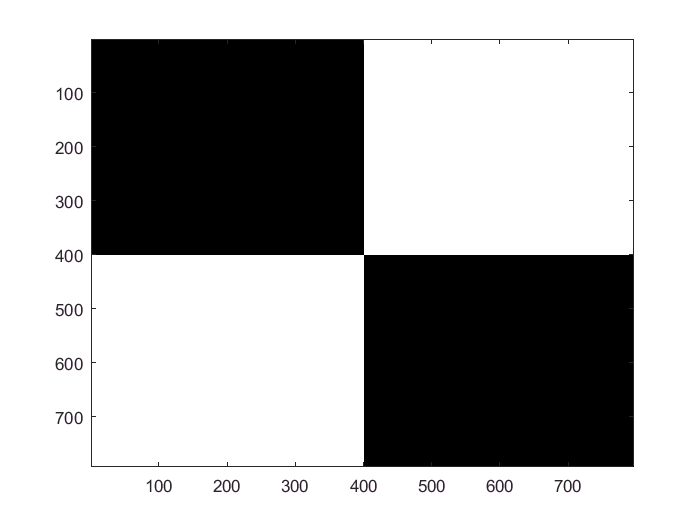

lit = imread('checkers.jpg');
T = double(lit(:,:,1));
clf
imagesc(T); colormap('gray');

T(T == 0) = -1;
T(T == 255) = 1;
T(T >= 128) = 1;
T(abs(T) ~= 1) = -1;
imagesc(T);

arrayT = reshape(T,631228,1);

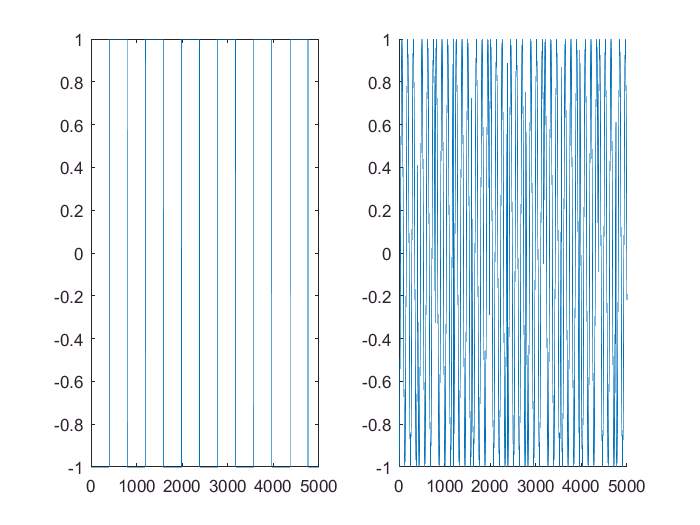

clf
subplot(1,2,1);
plot(arrayT);
xlim([0,5000])
mt = arrayT;                            %array of data
sampleTime = 10;                        %Total length of sample in time
sampleRate = (length(mt))/(sampleTime); %Number of samples per second
t = linspace(0,sampleTime,length(mt));           %array keeping time
w = (sampleRate/20);                     %frequency of cosine wave
c = cos(w*t);                           %array containing carrier wave
xt = mt.*c';                            %assembled signal containing carrier and signal waves
subplot(1,2,2);
hold on
plot(xt)
xlim([0,5000])
hold off

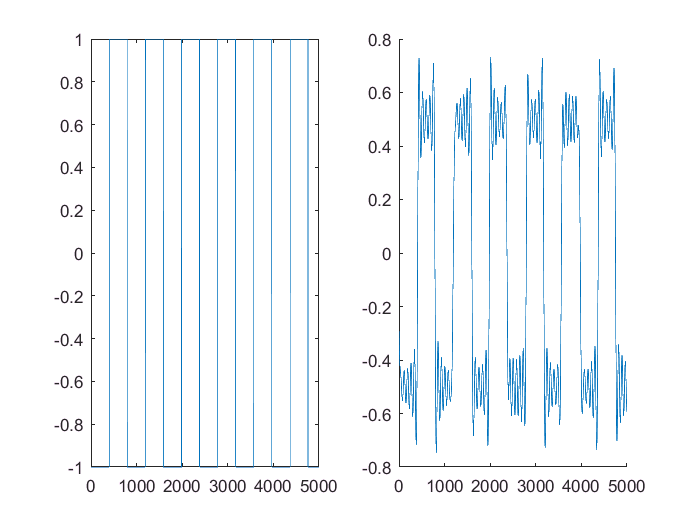

demodXt = xt'.*cos(w'.*t);
omc = (w*2*pi./sampleRate)*.28;
n = -1000:1000;
h = omc/pi*sinc(omc*n/pi);
filteredXt = conv(demodXt,h, 'same');
clf
subplot(1,2,1);
plot(arrayT);
xlim([0,5000])
subplot(1,2,2);
hold on
plot(filteredXt)
xlim([0,5000])
hold off